Cargar los archivos en formato Json

% Cargar datos desde un archivo JSON
fileName = 'PracticaKarts.json'; % Cargar el archivo
jsonData = jsondecode(fileread(fileName));
valores = jsonData.payload.values; % Matriz de datos de los sensores

Realizar la creación de los arreglos

% Número de muestras
n_muestras = length(valores);

% Preasignar los arreglos
accx = zeros(1, n_muestras);
accz = zeros(1, n_muestras);
gyroX = zeros(1, n_muestras);
gyroZ = zeros(1, n_muestras);

% Ciclo para asignar los valores
for i = 1:n_muestras
    accx(i) = jsonData.payload.values(i, 1);
    accz(i) = jsonData.payload.values(i, 3);
    gyroX(i) = jsonData.payload.values(i, 4);
    gyroZ(i) = jsonData.payload.values(i, 6); % Velocidad angular en Y
end

% Convertir las velocidades angulares de grados por segundo a radianes por segundo
gyroX = gyroX * (pi / 180); % Convertir a radianes por segundo
gyroZ = gyroZ * (pi / 180); % Convertir a radianes por segundo


Arrelgo de interpolación

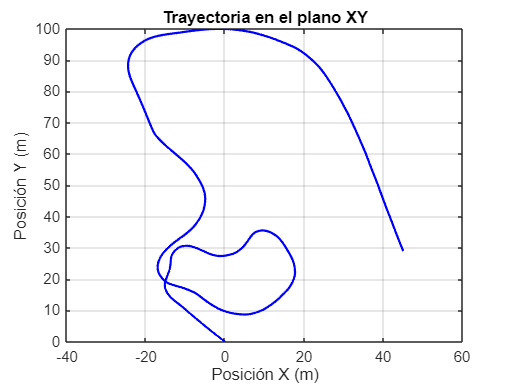


% Frecuencia de muestreo
fs = 1/0.016; % Frecuencia de muestreo (1/16ms)
t_discreta = (0:n_muestras-1) / fs; % Tiempo discreto

% Tiempo continuo para la interpolación
t_continua = linspace(t_discreta(1), t_discreta(end), 1000); % 1000 puntos interpolados

% Interpolación de las señales
accx_continua = interp1(t_discreta, accx, t_continua, 'linear');
accy_continua = interp1(t_discreta, accz, t_continua, 'linear');
gyroX_continua = interp1(t_discreta, gyroX, t_continua, 'linear');
gyroY_continua = interp1(t_discreta, gyroZ, t_continua, 'linear');

% Normalización de las aceleraciones para reducir la escala
accx_continua = accx_continua / max(abs(accx_continua)); % Normalizar a [0,1] o [-1,1]
accy_continua = accy_continua / max(abs(accy_continua)); % Normalizar a [0,1] o [-1,1]

% Cálculo de la velocidad en X y Y (integración de la aceleración)
vX_continua = cumtrapz(t_continua, accx_continua); % Velocidad en X
vY_continua = cumtrapz(t_continua, accy_continua); % Velocidad en Y

% Inicialización del ángulo
thetaX = cumsum(gyroX_continua) * (t_continua(2) - t_continua(1)); % Acumulación de la velocidad angular en X
thetaY = cumsum(gyroY_continua) * (t_continua(2) - t_continua(1)); % Acumulación de la velocidad angular en Y

% Aplicación de la rotación para las velocidades
vX_rot = vX_continua .* cos(thetaX) - vY_continua .* sin(thetaX); % Velocidad rotada en X
vY_rot = vX_continua .* sin(thetaX) + vY_continua .* cos(thetaX); % Velocidad rotada en Y

% Calcular la posición en X y Y (integración de la velocidad rotada)
x_continua = cumtrapz(t_continua, vX_rot); % Posición en X
y_continua = cumtrapz(t_continua, vY_rot); % Posición en Y

% Aplicar un factor de escala para asegurar que la posición no supere los 100 metros
max_pos = max([max(abs(x_continua)), max(abs(y_continua))]);
scale_factor = 100 / max_pos; % Factor de escala para limitar la posición máxima a 100 metros

x_continua = x_continua * scale_factor;
y_continua = y_continua * scale_factor;

% Graficar la trayectoria en el plano XY
figure;
subplot(1,1,1);
plot(x_continua, y_continua, 'b-', 'LineWidth', 1.5);
title('Trayectoria en el plano XY');
xlabel('Posición X (m)');
ylabel('Posición Y (m)');
grid on;